# To find VB1 energy value

## load the file and ask the user for E and K range

close all;
clear
selpath =uigetdir(' ');     %% to select the folder you want to work in
files = dir(fullfile(selpath,'*.txt'));     %% to store all the file names with .txt extension
filepath = fullfile({files.folder}, {files.name});     %% to generate filepaths for all the txt files in the folder

EK_Userbounds = inputdlg({'Enter the CB E upper bound (eV)','Enter the CB E lower bound (eV)','Enter the Xton E upper bound (eV)','Enter the Xton E lower bound (eV)','Enter the VB E upper bound (eV)','Enter the VB E lower bound (eV)','Enter the K upper bound (Angs-1)','Enter the K lower bound (Angs-1)'},...
              'Input the E and K range', [1 50; 1 50; 1 50; 1 50; 1 50; 1 50; 1 50; 1 50], {'2.75','2.25','2.25','1.75','0.5','-1', '-1', '-1.5'}); %% asking the user to enter the E and K bounds
EK_Userbounds = cellfun(@str2num,EK_Userbounds); %% to convert the cell values to array of number for easier access down the line


for cnt = 1:size(filepath,2)

##     read one of the the data file in the folder

    data = readmatrix(filepath{cnt}); %% to read the data file. Using readmatrix as we know the format of our file is floating and we want to use matrix form for ease of use later.
    Energy_Scale = data(2:size(data,1),1); %% scale generated from MM's code
    K_scale = data(1,2:size(data,2)); %% scale generated from MM's code
    data1 = data(2:size(data,1),2:size(data,2)); %% full data without the scales

##     creating the working data for CB, Xton and VB in the specified range

    E_UB_CB = find(abs(Energy_Scale- EK_Userbounds(1)) < 0.005);%% find the column number for the energy upper bound
    E_LB_CB = find(abs(Energy_Scale- EK_Userbounds(2)) < 0.005);%% find the column number for the energy lower bound
    E_UB_X = find(abs(Energy_Scale- EK_Userbounds(3)) < 0.005); 
    E_LB_X = find(abs(Energy_Scale- EK_Userbounds(4)) < 0.005);
    E_UB_VB = find(abs(Energy_Scale- EK_Userbounds(5)) < 0.005); 
    E_LB_VB = find(abs(Energy_Scale- EK_Userbounds(6)) < 0.004);
    K_UB = find(abs(K_scale- EK_Userbounds(7)) < 0.005);
    K_LB = find(abs(K_scale- EK_Userbounds(8)) < 0.005);
    
    if (EK_Userbounds(7)<0) && (EK_Userbounds(8)<0) %% to make sure the ranges are in correct order
        working_Kscale = K_scale(K_LB:K_UB); %% k scale for both VB and Xton
        working_data_CB = data1(E_UB_CB:E_LB_CB,K_LB:K_UB); %% working data for CB
        working_Escale_CB = Energy_Scale(E_UB_CB:E_LB_CB); %% working Escale for  CB
        working_data_X = data1(E_UB_X:E_LB_X,K_LB:K_UB); %% working data for Xton 
        working_Escale_X = Energy_Scale(E_UB_X:E_LB_X); %% working Escale for Xton 
        working_data_VB = data1(E_UB_VB:E_LB_VB,K_LB:K_UB); %% working data for VB
        working_Escale_VB = Energy_Scale(E_UB_VB:E_LB_VB); %% working data for VB
    
        working_data_CBX = data1(E_UB_CB:E_LB_X,K_LB:K_UB); %% working data for CB
        working_Escale_CBX = Energy_Scale(E_UB_CB:E_LB_X); %% working Escale for  CB
    elseif (EK_Userbounds(7)>0) && (EK_Userbounds(8)>0)
        working_Kscale = K_scale(K_UB:K_LB); %% k scale for both VB and Xton
        working_data_CB = data1(E_UB_CB:E_LB_CB,K_UB:K_LB); %% working data for CB
        working_Escale_CB = Energy_Scale(E_UB_CB:E_LB_CB); %% working Escale for  CB
        working_data_X = data1(E_UB_X:E_LB_X,K_UB:K_LB); %% working data for Xton 
        working_Escale_X = Energy_Scale(E_UB_X:E_LB_X); %% working Escale for Xton 
        working_data_VB = data1(E_UB_VB:E_LB_VB,K_UB:K_LB); %% working data for VB
        working_Escale_VB = Energy_Scale(E_UB_VB:E_LB_VB); %% working data for VB
    
        working_data_CBX = data1(E_UB_CB:E_LB_X,K_UB:K_LB); %% working data for CB
        working_Escale_CBX = Energy_Scale(E_UB_CB:E_LB_X); %% working Escale for  CB
    end

##     plot the working data

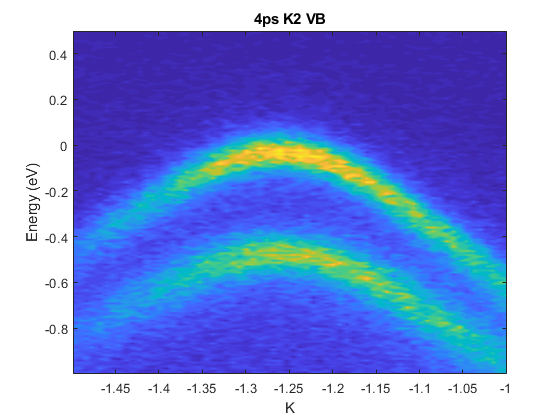

%     [A,h] = contourf(working_Kscale, working_Escale_CBX, working_data_CBX, 50); %% here h can be used to set the parameters of the contour after plotting
%     set(h,'LineColor','none') %% to not have contour lines in the plots
    
%     [B,h] = contourf(working_Kscale, working_Escale_X, working_data_X, 50); %% here h can be used to set the parameters of the contour after plotting
%     set(h,'LineColor','none') 
    new_file_name = split(files(cnt).name,'_');
    
    [C,h] = contourf(working_Kscale, working_Escale_VB, working_data_VB, 50); %% here h can be used to set the parameters of the contour after plotting
    set(h,'LineColor','none');
    yl = ylim; xl = xlim; grid off; %legend(new_file_name{1},' double gaussian fit'); 
    title([new_file_name{1} , ' K2 VB']); xlabel('K'); ylabel('Energy (eV)');ax = gca; %% ax is to specify the axis type. gca means current axis
    exportgraphics(ax, fullfile(files(cnt).folder,'parameters',strcat('time = ',new_file_name{1}, ' K2 VB.png'))); %% to export the plots for later check
    
    wKdata = [working_Escale_VB, working_data_VB];
    wKscale = [0, working_Kscale];
    
    writetable(array2table(cat(1,wKscale,wKdata)), fullfile(files(cnt).folder,'parameters',strcat(new_file_name{1},'_zoomed_K2_VB.txt')), "Delimiter",'tab',"WriteMode","append"); %% to write the output of the parameters after fitting

    
end